# Bridge circuits 

Copyright (C) 2021 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

## Introduction

In this notebook, we will introduce the bridge circuit, and show how to connect it to the instrumentation amplifier and how to linearize it.

## Bridge circuit

Bridge circuit is show for the figure below. The outout is shown when the resistor R3 changed its value from in the range of 3%.

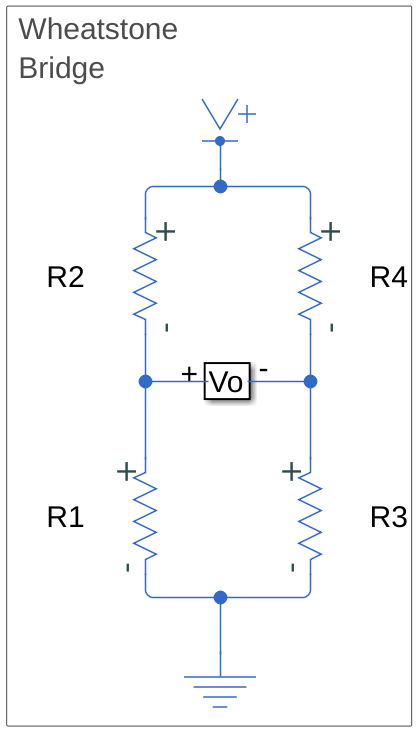

% Balanced bridge
model_name = 'bridge1';
open_system(model_name);
set_param('bridge1/R1','R','120');
set_param('bridge1/R2','R','120');
set_param('bridge1/R3','R','120');
set_param('bridge1/R4','R','120');
simOut = sim('bridge1', 'CaptureErrors', 'on');

## Quarter bridge

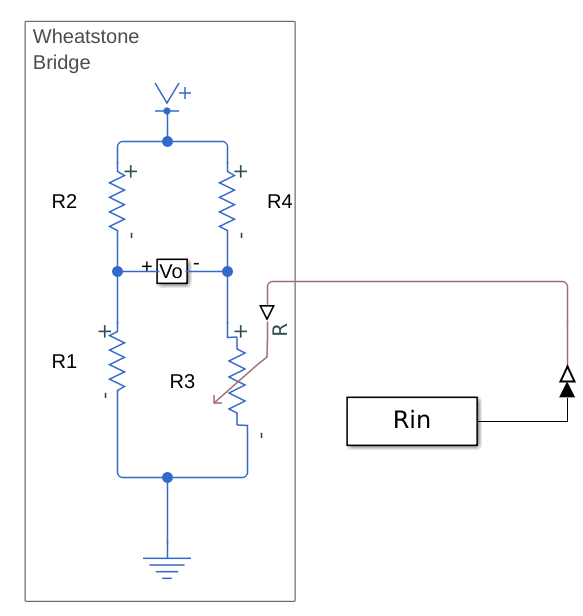

% Changing input resistance of R3 over 2 sec from 120Ohm -3% to 120 +3%
T=0.001;
Rin(:,1)=T:T:2; %time;
percentage_change=3;
R_nominal=120;
R_range=[R_nominal-R_nominal*percentage_change/100, R_nominal+R_nominal*percentage_change/100];
deltaR=(R_range(2)-R_range(1))/length(Rin(:,1));
Rin(:,2)=R_range(1):deltaR:R_range(2)-deltaR;

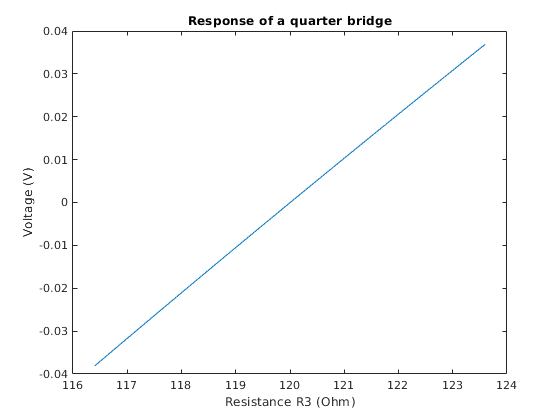

%Quarter bridge
model_name = 'quarter_bridge';
open_system(model_name);
set_param('quarter_bridge/R1','R','120');
set_param('quarter_bridge/R2','R','120');
set_param('quarter_bridge/R4','R','120');
simOut1 = sim('quarter_bridge', 'CaptureErrors', 'on');

figure
plot(Rin(:,2),simOut1.voltage_out.Data(1:length(Rin(:,2)),1))
title('Response of a quarter bridge')
xlabel('Resistance R3 (Ohm)')
ylabel('Voltage (V)')

## Quarter bridge with the instrumentation amplifier

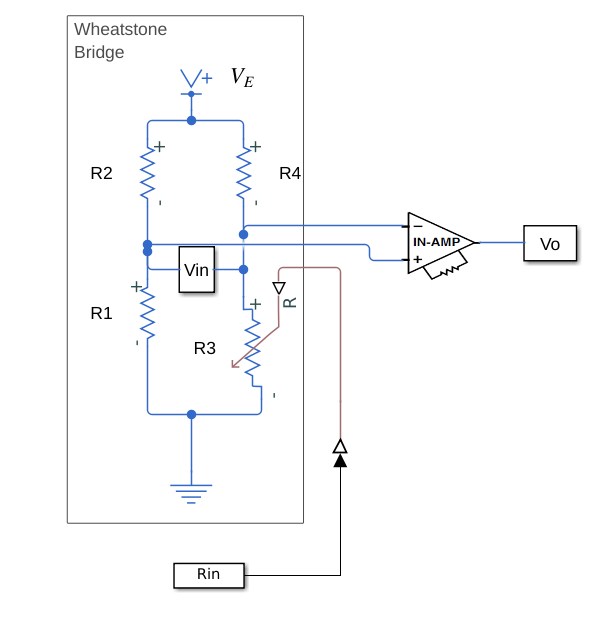


T=0.001;
t=T:T:2;
Rin(:,1)= t; %time;
percentage_change=3;
R_nominal=120;

Rin(:,2)=R_nominal+sin(2*pi*1.2*t); 

%Quarter bridge
% Get simulation results
model_name = 'quarter_bridge_with_IA';
open_system(model_name);
set_param('quarter_bridge_with_IA/R1','R','120');
set_param('quarter_bridge_with_IA/R2','R','120');
set_param('quarter_bridge_with_IA/R4','R','120');
out=sim(model_name)

out =   Simulink.SimulationOutput:

              ScopeData: [1x1 struct] 
                logsout: [1x1 Simulink.SimulationData.Dataset] 
                 simout: [1x1 timeseries] 
                   tout: [6126x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


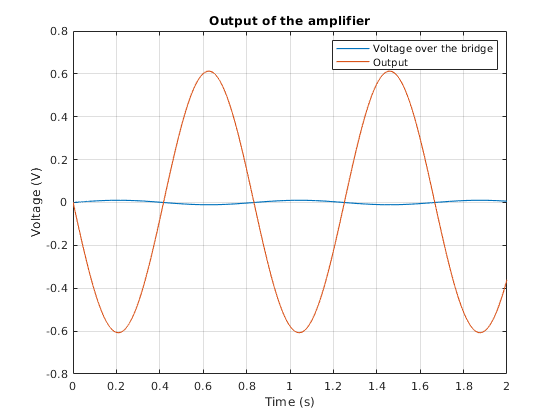

temp_vin = out.simout.Data(:,1);
temp_vout = out.simout.Data(:,2);

% Plot results
figure
plot(out.simout.Time,temp_vin,'LineWidth',1);
hold on
plot(out.simout.Time,temp_vout,'LineWidth',1);
hold off
grid on
title('Output of the amplifier');
ylabel('Voltage (V)');
xlabel('Time (s)');
xlim([0,2])
legend({'Voltage over the bridge','Output'});

## Linearized quarter bridge

% Changing input resistance of R3 over 2 sec from 120Ohm -3% to 120 +3%
T=0.001;
t=T:T:2;
Rin(:,1)=T:T:2; %time;
percentage_change=3;
R_nominal=120;

Rin(:,2)=R_nominal+sin(2*pi*1.2*t); 

model_name = 'LinearizedBridge';
out=sim(model_name)

out =   Simulink.SimulationOutput:

              ScopeData: [1x1 struct] 
                logsout: [1x1 Simulink.SimulationData.Dataset] 
                 simout: [1x1 timeseries] 
                   tout: [5932x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


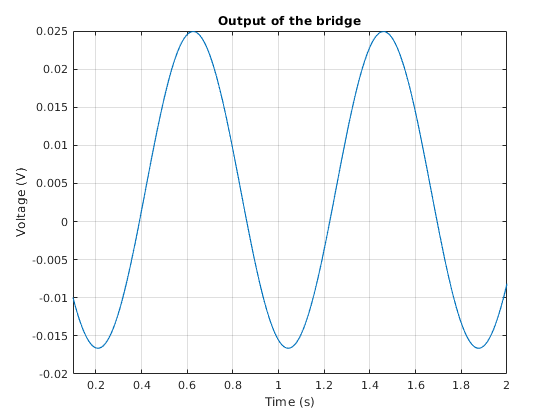

temp_vin = out.simout.Data(:,1);
temp_vout = out.simout.Data(:,2);

% Plot results
figure
%plot(out.simout.Time,temp_vin,'LineWidth',1);
%hold on
plot(out.simout.Time,temp_vout,'LineWidth',1);
hold off
grid on
title('Output of the bridge');
ylabel('Voltage (V)');
xlabel('Time (s)');
xlim([0.1,2])

%ylim([-0.1,0.1])
%legend({'Voltage over the bridge','Output'});

R_range=[R_nominal-R_nominal*percentage_change/100, R_nominal+R_nominal*percentage_change/100];
deltaR=(R_range(2)-R_range(1))/length(Rin(:,1));
Rin(:,2)=R_range(1):deltaR:R_range(2)-deltaR;

out=sim(model_name)

out =   Simulink.SimulationOutput:

              ScopeData: [1x1 struct] 
                logsout: [1x1 Simulink.SimulationData.Dataset] 
                 simout: [1x1 timeseries] 
                   tout: [6006x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


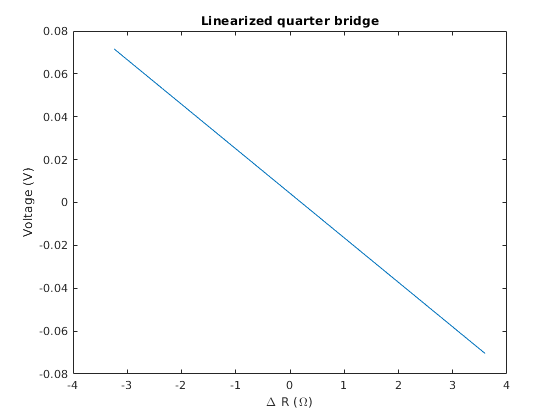

temp_vin = out.simout.Data(:,1);
temp_vout = out.simout.Data(:,2);

% Plot results
figure

figure
plot(Rin(100:end,2)-R_nominal,temp_vout(100:end-1))
title('Linearized quarter bridge')
xlabel('\Delta R (\Omega)')
ylabel('Voltage (V)')

## Exersizes

Excersize 1: What is the Sensitivity of the quarter bridge if the sensitivity is computed as range of the output voltages/reference voltage?